# Predicting Global Solar Radiation

This demo creates and tests a temperature- and humidity-based model to estimate mean daily global solar radiation. As the sun's radiation penetrates the atmosphere, a portion of the radiation is scattered, reflected or absorbed. The amount reaching the Earth's surface (either directly or through scattering) is known as global solar radiation. Maximum daily temperature, minimum daily temperature, and average daily humidity are used to estimate the ratio of global solar radiation to extraterrestrial radiation (i.e. the ratio between the amount of radiation that hits the surface of the Earth and that which hits the top of the atmosphere).

## Load Data from Excel File

Data modified from data taken in Davis, CA from 2001-2010 by the California Irrigation Management Information System, Department of Water Resources. ([http://www.cimis.water.ca.gov/cimis/data.jsp](http://www.cimis.water.ca.gov/cimis/data.jsp))

filename = 'DavisDaily.xlsx';

% Function created interactively using the Import Tool
[Date,DayOfYear,SolRatio,MaxAirTemp,MinAirTemp,AvgRelHum] =...
    importSolarData(filename);

## Look at Loaded Solar Ratio

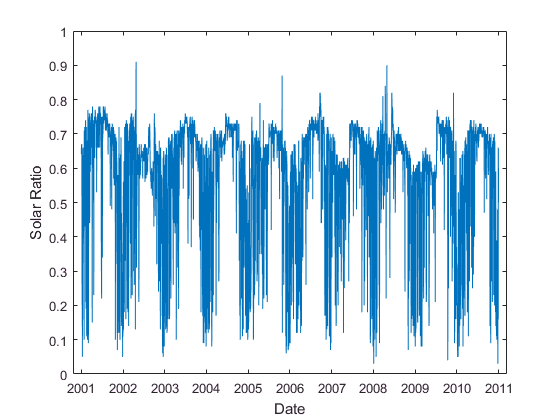

figure
plot(Date,SolRatio)
ylabel('Solar Ratio')
xlabel('Date')

## Get Year Information

Year = year(Date);

## Visualize Ratio of Global and Extraterrestrial Radiation

The ratio of global solar radiation is not constant. It varies throughout the year and also by year. It may significantly vary depending on local weather conditions and season. Solar energy refraction and attenuation is caused by complex processes related to cloud cover, moisture content, and other atmospheric impurities.

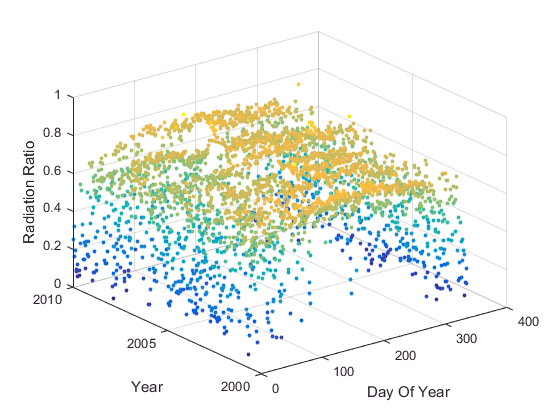

figure
scatter3(DayOfYear,Year,SolRatio,10,SolRatio,'filled')
xlabel('Day Of Year')
ylabel('Year')
zlabel('Radiation Ratio')


% Note that the rainy season for Davis is from late fall to early spring
% (October to April -- approximate DayOfYear, 1-91 and 274-365)

## Set Aside Data for Testing

We set aside a set of data which will be used later to test our estimation. We build our model on the remaining data. In this case, we choose a set in the middle of our data set, the year 2006.

idx = Year == 2006;

delT = MaxAirTemp - MinAirTemp;

delTTest = delT(idx);
AvgRelHumTest = AvgRelHum(idx);
SolRatioTest = SolRatio(idx);
DayOfYearTest = DayOfYear(idx);

## Fit Formula to Data

The following formula is used to predict the ratio of global solar radiation to extraterrestrial radiation as a function of daily temperature variaions and relative humidity. The following formula describes large-scale behavior, and it is similar to those used in other studies. This demo focuses on the technique and not the specific equation used.


$$R_s = a*(1-b*H)*(1 - \exp(-c (\Delta T)^n))$$


where:


$$ \Delta T = T_{DailyMax} - T_{DailyMin} $$


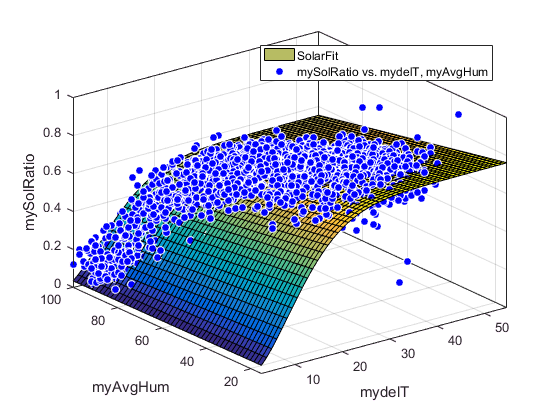

% Remove test data from original data set and build model on what's left
delT(idx) = [];
AvgRelHum(idx) = [];
SolRatio(idx) = [];

% Function created interactively using Curve Fitting App
[model, gof] = createSolarFit(delT,AvgRelHum,SolRatio);


disp(model)


     General model:
     model(delT,RelHum) = a*(1+b*RelHum)*(1-exp(-c*delT^n))
     Coefficients (with 95% confidence bounds):
       a =      0.7995  (0.786, 0.8129)
       b =   -0.003053  (-0.003328, -0.002777)
       c =     0.01015  (0.007716, 0.01258)
       n =       1.757  (1.666, 1.847)



## Estimate Solar Ratio

EstRad = model(delTTest,AvgRelHumTest);
PredInt = predint(model,[delTTest AvgRelHumTest]);

## Plot Estimated and Measured Solar Ratio

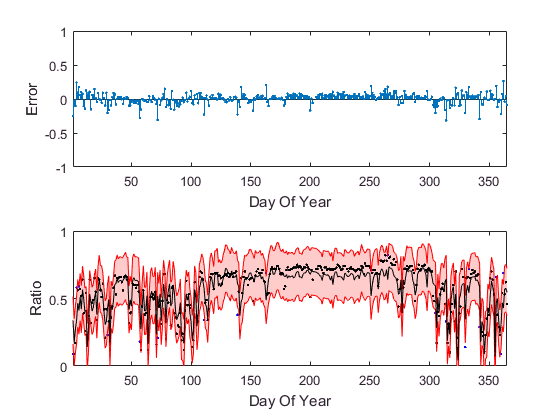

createFitFigure(DayOfYearTest,EstRad,PredInt,SolRatioTest)

## Calculate Percent of Points within Estimated Bounds

inside = SolRatioTest >= PredInt(:,1) & SolRatioTest <= PredInt(:,2);
percentFit = nnz(inside)/length(inside)*100;

fprintf('%5.3f percent of data points are within estimated bounds\n',...
    percentFit);

94.751 percent of data points are within estimated bounds


*Copyright 2012-2017 The MathWorks, Inc.*